# Sample 11-4

## 画像ノイズ除去

勾配降下法

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Image denoising

Gradient descent

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

clear 
close all
import msip.download_img
msip.download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


## 問題設定

(Problem settings)

    
$$\hat{\mathbf{s}}=\arg\min_{\mathbf{s}}\frac{1}{2}\|\mathbf{v}-\mathbf{Ds}\|_2^2+\frac{\lambda}{2}\|\mathbf{s}\|_2^2$$


- 
$$\mathbf{D} = \left(\begin{array}{cc} \frac{2}{3} & \frac{1}{3}\end{array}\right)\colon\quad \mathbb{R}^2\rightarrow\mathbb{R}^1$$


- 
$$\mathbf{v}=\frac{1}{2}\in\mathbb{R}^1$$


- 
$$\lambda\in[0,\infty)$$


- 
$$\mathbf{s}\in\mathbb{R}^2$$


D = [2 1]/3;
v = 0.5;

### パラメータ設定

(Parameter settings)

lambda = 0.2;
gamma = 0.4;
niters = 20;

### 関数プロット

(Function plot)

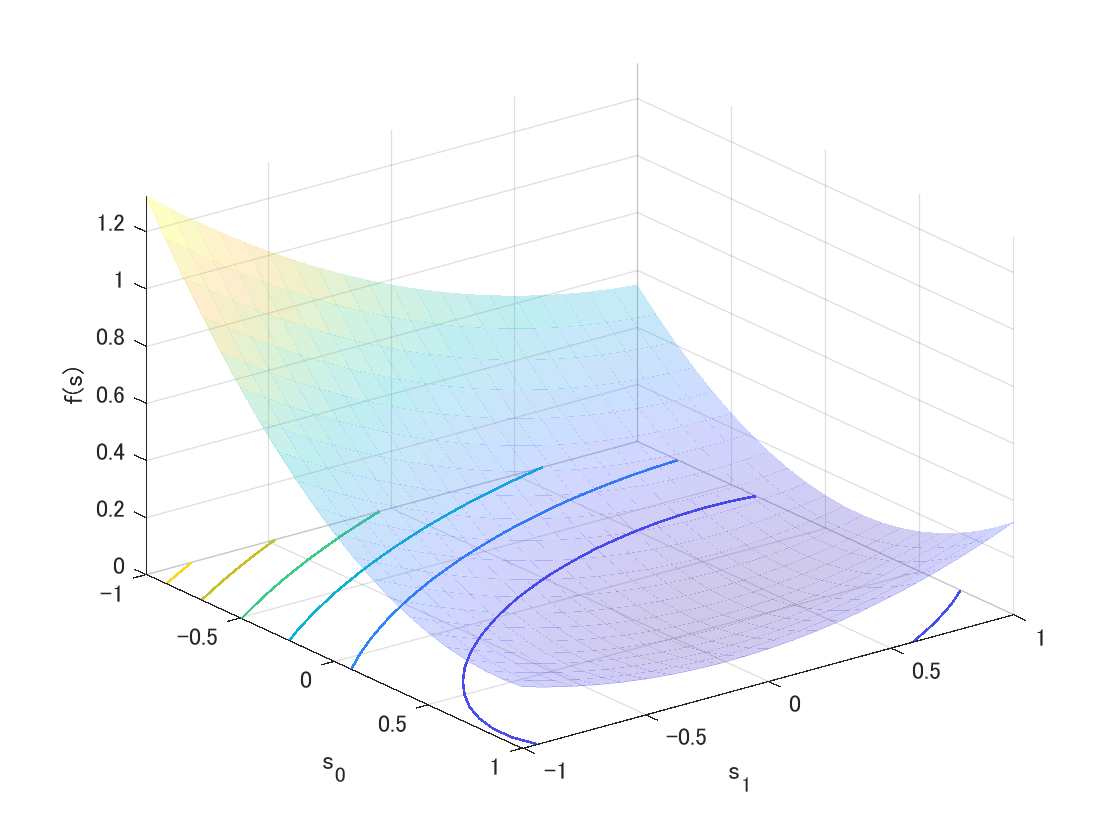

% Function setting
f = @(x0,x1) 0.5*(v-(D(1)*x0+D(2)*x1)).^2 + lambda*0.5*(x0.^2+x1.^2);
% Variable settings
s0 = linspace(-1,1,21);
s1 = linspace(-1,1,21);
% Surfc plot of cost function f()
figure(1)
[S0,S1] = ndgrid(s0,s1);
J = f(S0,S1);
hf = surfc(s0,s1,J);
hf(1).FaceAlpha = 0.25;
hf(1).EdgeAlpha = 0.25;
hf(1).EdgeColor = 'interp';
hf(2).LineWidth = 1;
set(gca,'YDir','reverse')
ylabel('s_0')
xlabel('s_1')
zlabel('f(s)')
hold on

### 勾配降下法

(Gradient descent)

- Initialization: $\mathbf{x}^{(0)}$, $t\leftarrow 0$

- Gradient descent: $\mathbf{x}^{(t+1)}\leftarrow \mathbf{x}^{(t)}-\gamma\nabla_\mathbf{x}f(\mathbf{x}^{(t)})$

- If a stopping critera is satisfied then finish, otherwise $t\rightarrow t+1$ and go to Step 2.

【Example】

- 
$$f(\mathbf{s})=\frac{1}{2}\|\mathbf{v}-\mathbf{Ds}\|_2^2+\frac{\lambda}{2}\|\mathbf{s}\|_2^2$$


- 
$$\nabla_\mathbf{s}f(\mathbf{s})=\mathbf{D}^T(\mathbf{Ds}-\mathbf{v})+\lambda\mathbf{s}$$


初期化 (Initialization)

sp = 2*rand(2,1)-1; % in [-1,1]^2

勾配降下 (Gradient descent)

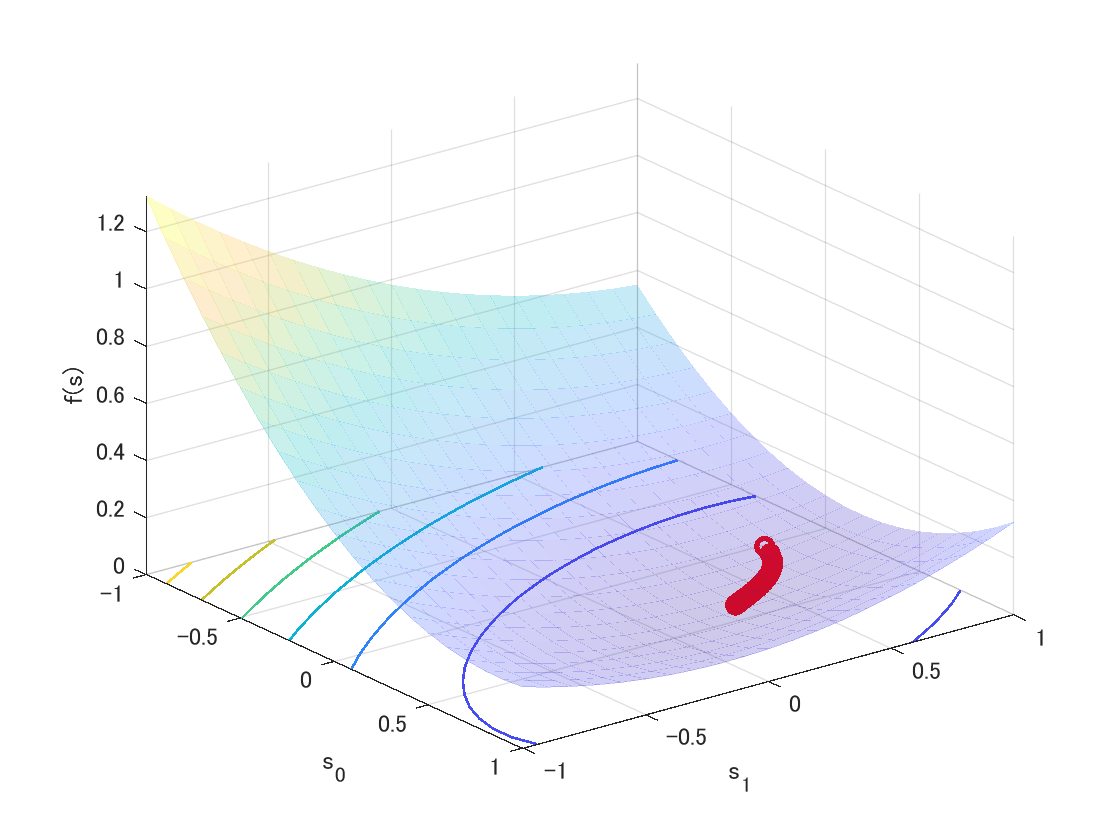

for idx=0:niters-1
    % Preious state
    s(1,1) = sp(1); % s0
    s(2,1) = sp(2); % s1
    % Gradient descent
    sc = sp-gamma*(D'*(D*sp-v)+lambda*sp);
    % Current state
    s(1,2) = sc(1); % s0
    s(2,2) = sc(2); % s1
    % Quiver plot
    xp = s(2,1);
    yp = s(1,1);
    xn = s(2,2);
    yn = s(1,2);
    hp = quiver(xp,yp,xn-xp,yn-yp);
    hp.Marker = 'o';
    hp.ShowArrowHead = 'on';
    hp.MaxHeadSize = 120;
    hp.MarkerSize = 6;
    hp.MarkerEdgeColor = 'r';
    hp.Color = 'r';
    hp.LineWidth = 2;
    % Update
    sp = sc;
end
hold off

### パラメータ設定

(Parameter settings)

- sgm: ノイズ標準偏差 $\sigma_w$ (Standard deviation of noise)

- nlevels: ウェーブレット段数 (Wavelet levels)

% Parameter settings
isaprxleft = true;
lambda = 10^1

lambda = 10

gamma = 10^-1

gamma = 0.1000

sgmuint8 = 20; 
sgm = sgmuint8/255;
nlevels = 3; 
niters = 80;

## 画像の読込

(Read image)

u = rgb2gray(im2double(imread('./data/lena.png')));

## 観測画像

(Observation image)

- 
$$\mathbf{v}=\mathbf{u}+\mathbf{w}$$


- 
$$\mathbf{u}=\mathbf{Ds}$$


- 
$$\mathbf{s}\sim\mathrm{Norm}\left(\mathbf{s}|\mathbf{\mu}=\mathbf{0},\sigma_s^2\mathbf{I}\right)$$


- 
$$\mathbf{w}\sim\mathrm{Norm}\left(\mathbf{w}|\mathbf{\mu}_w=\mathbf{0},\sigma_w^2\mathbf{I}\right)$$


v = imnoise(u,'gaussian',0,sgm^2);

### 非間引きハールDWT

(Undecimated Haar DWT)

import msip.udhaarwtdec2
import msip.udhaarwtrec2

#### 完全再構成の確認 (Checki the perfect reconstruction)

非間引きハールDWTはパーセバルタイト性 (The undecimated DWT satisfies the Parseval tight property,)

        
$$\mathbf{DD}^T=\mathbf{I}$$


を満たすため， $\mathbf{D}$ の転置システムは完全再構成分析システムとなり得る．(and thus Its transposition system can be a PR analysis system.)

[coefs,scales] = udhaarwtdec2(u,nlevels);
r = udhaarwtrec2(coefs,scales);
assert(norm(u-r,"fro")^2/numel(u)<1e-18,'Perfect reconstruction is violated.')

合成辞書と転置辞書の定義 (Definition of synthesis dictionary  and its adjoint)

% Definiton of dictionay and its adjoint
adjdic = @(x) udhaarwtdec2(x,nlevels); % D
syndic = @(x) udhaarwtrec2(x,scales);  % D.'

### 勾配降下法

(Gradient descent method)

- Initialization: $\mathbf{x}^{(0)}$, $t\leftarrow 0$

- Gradient descent: $\mathbf{x}^{(t+1)}\leftarrow \mathbf{x}^{(t)}-\gamma\nabla_\mathbf{x}f(\mathbf{x}^{(t)})$

- If a stopping critera is satisfied then finish, otherwise $t\rightarrow t+1$ and go to Step 2.

【Example】

- 
$$f(\mathbf{s})=\frac{1}{2}\|\mathbf{v}-\mathbf{Ds}\|_2^2+\frac{\lambda}{2}\|\mathbf{s}\|_2^2$$


- 
$$\nabla_\mathbf{s}f(\mathbf{s})=\mathbf{D}^T(\mathbf{Ds}-\mathbf{v})+\lambda\mathbf{s}$$


初期化 (Initialization)

sp = coefs;

勾配降下 (Gradient descent)

if isaprxleft
    mask = ones(size(coefs));
    mask(1:prod(scales(1,:))) = 0;
    lambda = lambda * mask;
end
for idx=0:niters-1
    % Gradient descent
    sc = sp-gamma*(adjdic(syndic(sp)-v)+lambda.*sp);
    % Update
    sp = sc;
end

### ノイズ除去画像

(Denoised image)

r = syndic(sc);

### 画像表示

(Image show)

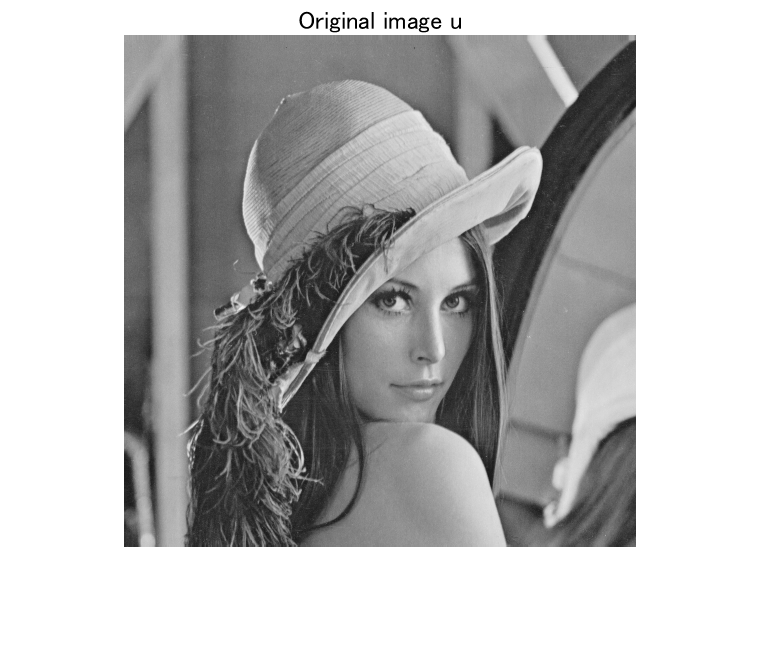

figure(1)
imshow(u);
title('Original image u')

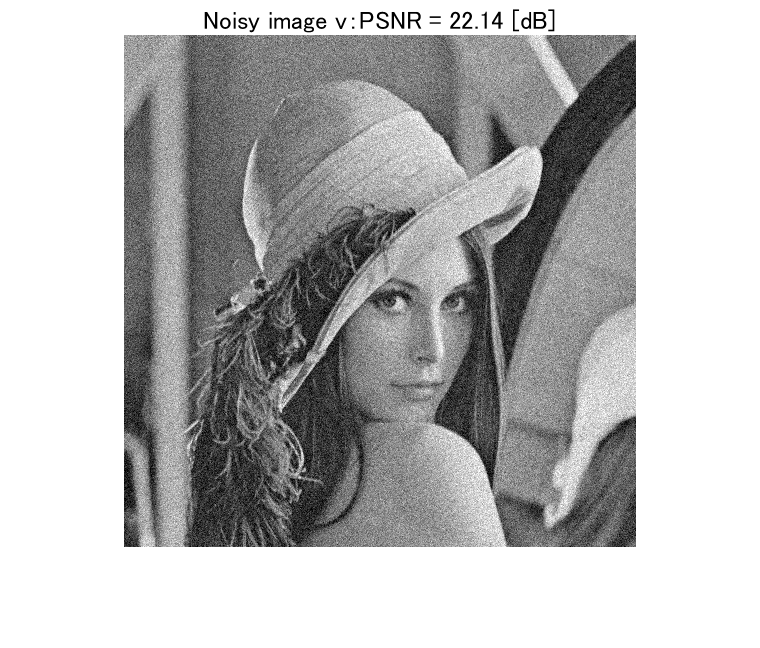

figure(2)
imshow(v)
title(sprintf('Noisy image v：PSNR = %5.2f [dB]',psnr(u,v)))

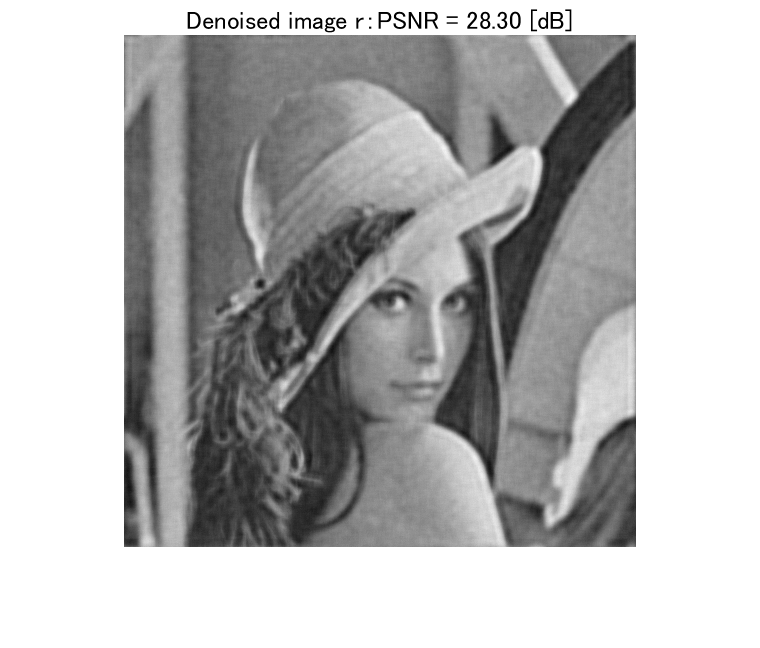

figure(3)
imshow(r)
title(sprintf('Denoised image r：PSNR = %5.2f [dB]',psnr(u,r)))

© Copyright, Shogo MURAMATSU, All rights reserved.